# Generating the impact map for the three-link 2D biped (Assignment 2, continued)

Once the biped completes a step, the swing foot hits the ground and afterwards the swing leg becomes the **new** stance leg and the stance leg becomes the **new** swing leg.  The **impact map,** which this scripts generates, defines such a transition. Indeed, the impact map, maps the state of the robot right before the impact to its state right after the impact. Mathematically, **assuming the impact and switching of the legs roles is instantenous**, we have 


$$\Delta(q^-, \dot q^-) = (q^+, \dot q^+)$$


where $(q^-, \dot q^-)$ is the state of the robot right before the impact and $(q^+, \dot q^+)$ denotes its state right after the impact. This script generates the impact map $\Delta$. 

**Note**: In this script we use the notation [q1_m, q2_m, q3_m] for $q^-$ and [q1_p, q2_p, q3_p] for $q^+$. Similarly, we use [dq1_m, dq2_m, dq3_m] for $\dot q^-$ and [dq1_p, dq2_p, dq3_p] for $\dot q^+$.

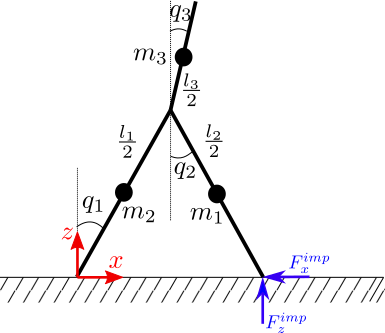

## Angles:

We can write the impact map as:


$$\Delta(q^-, \dot q^-) = (\Delta_q(q^-), \Delta_{\dot q} (q^-, \dot q^-))$$


This is true, because before and after impact the configuration of the robot (not the velocites) remains the same. So, for $\Delta_q$ all you need is to **swap** the indices of the stance and swing legs appropriately, taking into account that we always use index 1 for the stance leg and index 2 for the swing leg. You will be doing this directly in the impact.m function. 

syms q1_m q2_m q3_m q1_p q2_p q3_p

## Angular Velocities:

Unlike angles, which only needed bookeeping, calculation of angular velocities (i.e., $\dot q^+$) needs some physics. We will follow the approach of [McGeer 1988](https://aerovel.com/wp-content/uploads/2015/03/Stability-and-control-of-two-dimensional-bipedal-walking.pdf), i.e. method of **conservation of angular momentum** to calculate the angular velocities after impact. 

In the following cells you need the symbolic outputs of generate_kinematics. So, we first run generate_kinematics:

**Note: Before running generate_kinematics,** **update it to include velocities of (x_h, z_h) and (x_swf, z_swf) that is (dx_h, dz_h) and (dx_swf, dz_swf). Later we will be using them.** 

generate_kinematics

$$x\_h = l_{1}\,\sin\left(q_{1}\right)$$

$$z\_h = l_{1}\,\cos\left(q_{1}\right)$$

$$x\_swf = l_{1}\,\sin\left(q_{1}\right)-l_{2}\,\sin\left(q_{2}\right)$$

$$z\_swf = l_{1}\,\cos\left(q_{1}\right)-l_{2}\,\cos\left(q_{2}\right)$$

$$x\_t = l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\sin\left(q_{3}\right)$$

$$z\_t = l_{1}\,\cos\left(q_{1}\right)+l_{3}\,\cos\left(q_{3}\right)$$

$$dx\_h = {\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)$$

$$dz\_h = -{\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)$$

$$dx\_swf = {\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)-{\mathrm{dq}}_{2}\,l_{2}\,\cos\left(q_{2}\right)$$

$$dz\_swf = {\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{2}\right)-{\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)$$

For the calculation of angular momentum before and after impact you first need to calculate the positions and velocites of the masses $m_1$, $m_2$ and $m_3$ as well as the hip joint before and after impact.

**Positions and velocities of the masses and the hip joint before the impact:**

syms dq1_m dq2_m dq3_m dq1_p dq2_p dq3_p
x1_m = subs(x1, {q1, q2, q3}, {q1_m, q2_m, q3_m});
z1_m = subs(z1, {q1, q2, q3}, {q1_m, q2_m, q3_m});
x2_m = subs(x2, {q1, q2, q3}, {q1_m, q2_m, q3_m});
z2_m = subs(z2, {q1, q2, q3}, {q1_m, q2_m, q3_m});
x3_m = subs(x3, {q1, q2, q3}, {q1_m, q2_m, q3_m});
z3_m = subs(z3, {q1, q2, q3}, {q1_m, q2_m, q3_m});
xh_m = subs(x_h, {q1, q2, q3}, {q1_m, q2_m, q3_m});
zh_m = subs(z_h, {q1, q2, q3}, {q1_m, q2_m, q3_m});
xswf_m = subs(x_swf, {q1, q2, q3}, {q1_m, q2_m, q3_m});
zswf_m = subs(z_swf, {q1, q2, q3}, {q1_m, q2_m, q3_m});
 
dx1_m = diff(x1_m, q1_m)*dq1_m + diff(x1_m, q2_m)*dq2_m + diff(x1_m, q3_m)*dq3_m;
dz1_m = diff(z1_m, q1_m)*dq1_m + diff(z1_m, q2_m)*dq2_m + diff(z1_m, q3_m)*dq3_m;
dx2_m = diff(x2_m, q1_m)*dq1_m + diff(x2_m, q2_m)*dq2_m + diff(x2_m, q3_m)*dq3_m;
dz2_m = diff(z2_m, q1_m)*dq1_m + diff(z2_m, q2_m)*dq2_m + diff(z2_m, q3_m)*dq3_m;
dx3_m = diff(x3_m, q1_m)*dq1_m + diff(x3_m, q2_m)*dq2_m + diff(x3_m, q3_m)*dq3_m;
dz3_m = diff(z3_m, q1_m)*dq1_m + diff(z3_m, q2_m)*dq2_m + diff(z3_m, q3_m)*dq3_m;
dxh_m = diff(xh_m, q1_m)*dq1_m + diff(xh_m, q2_m)*dq2_m + diff(xh_m, q3_m)*dq3_m;
dzh_m = diff(zh_m, q1_m)*dq1_m + diff(zh_m, q2_m)*dq2_m + diff(zh_m, q3_m)*dq3_m;
dxswf_m = diff(xswf_m, q1_m)*dq1_m + diff(xswf_m, q2_m)*dq2_m + diff(xswf_m, q3_m)*dq3_m;
dzswf_m = diff(zswf_m, q1_m)*dq1_m + diff(zswf_m, q2_m)*dq2_m + diff(zswf_m, q3_m)*dq3_m;

**Positions and velocities of the masses and the hip joint after the impact:**

x1_p = subs(x2, {q1, q2, q3}, {q1_p, q2_p, q3_p});
z1_p = subs(z2, {q1, q2, q3}, {q1_p, q2_p, q3_p});
x2_p = subs(x1, {q1, q2, q3}, {q1_p, q2_p, q3_p});
z2_p = subs(z1, {q1, q2, q3}, {q1_p, q2_p, q3_p});
x3_p = subs(x3, {q1, q2, q3}, {q1_p, q2_p, q3_p});
z3_p = subs(z3, {q1, q2, q3}, {q1_p, q2_p, q3_p});
xh_p = subs(x_h, {q1, q2, q3}, {q1_p, q2_p, q3_p});
zh_p = subs(z_h, {q1, q2, q3}, {q1_p, q2_p, q3_p});
xswf_p = subs(x_swf, {q1, q2, q3}, {q1_p, q2_p, q3_p});
zswf_p = subs(z_swf, {q1, q2, q3}, {q1_p, q2_p, q3_p});

dx1_p = diff(x1_p, q1_p)*dq1_p + diff(x1_p, q2_p)*dq2_p + diff(x1_p, q3_p)*dq3_p;
dz1_p = diff(z1_p, q1_p)*dq1_p + diff(z1_p, q2_p)*dq2_p + diff(z1_p, q3_p)*dq3_p;
dx2_p = diff(x2_p, q1_p)*dq1_p + diff(x2_p, q2_p)*dq2_p + diff(x2_p, q3_p)*dq3_p;
dz2_p = diff(z2_p, q1_p)*dq1_p + diff(z2_p, q2_p)*dq2_p + diff(z2_p, q3_p)*dq3_p;
dx3_p = diff(x3_p, q1_p)*dq1_p + diff(x3_p, q2_p)*dq2_p + diff(x3_p, q3_p)*dq3_p;
dz3_p = diff(z3_p, q1_p)*dq1_p + diff(z3_p, q2_p)*dq2_p + diff(z3_p, q3_p)*dq3_p;
dxh_p = diff(xh_p, q1_p)*dq1_p + diff(xh_p, q2_p)*dq2_p + diff(xh_p, q3_p)*dq3_p;
dzh_p = diff(zh_p, q1_p)*dq1_p + diff(zh_p, q2_p)*dq2_p + diff(zh_p, q3_p)*dq3_p;
dxswf_p = diff(xswf_p, q1_p)*dq1_p + diff(xswf_p, q2_p)*dq2_p + diff(xswf_p, q3_p)*dq3_p;
dzswf_p = diff(zswf_p, q1_p)*dq1_p + diff(zswf_p, q2_p)*dq2_p + diff(zswf_p, q3_p)*dq3_p;

Positions and velocites before and after impact in vector form:

% r1_m =
% r2_m =
% r3_m =
% rh_m =
% rswf_m =
% r1_p =
% r2_p =
% r3_p =
% rh_p =
% rswf_p =
% dr1_m =
% dr2_m =
% dr3_m =
% drh_m =
% drswf_m =
% dr1_p =
% dr2_p =
% dr3_p =
% drh_p =
% drswf_p =

% we define this function to calcuate the cross products of 2d vectors.
 cross2d = @(v1, v2) (v1(1) * v2(2) - v2(1) * v1(2));

## Calculate angular momentums before and after impact:

We calculate the required angular momentums (as disscussed in the class) before and after impact around the swing foot end and the hip joint. 

 syms m m3 % note m1 = m2 = m
% Ha_m = % total angular momentum around the swing foot before impact 
% Ha_p = % total angular momentum around the now stance foot (after impact)
% Hb_m = % angular momentum of the stance leg around the hip joint (before impact)
% Hb_p = % angular momentum of the now swing leg around the hip joint (after impact)
% Hc_m = % angular momentum of the torso around the hip joint (before impact)
% Hc_p = % angular momentum of the torso around the hip joint (after impact)

 H_m = [Ha_m; Hb_m; Hc_m];

Undefined function or variable 'Ha_m'.

 H_p = [Ha_p; Hb_p; Hc_p];
 H_m = simplify(H_m, 'steps', 50);
 H_p = simplify(H_p, 'steps', 50);

## Conservation of angular momentums:

Based on the discussion in class, conservation of angular momentum exists for segments of the robot around the hip joint and swing foot at impact, and hence:


$$H_m = H_p$$


We can rewrite $H_m$ as $A_{-} \dot q^-$ and $H_p$ as $A_{+} \dot q^+$. Thus,


$$\dot q^+ = A_{+}^{-1}A_{-} \dot q^-$$


Eq_l = collect(H_m, [dq1_m, dq2_m, dq3_m])
Eq_r = collect(H_p, [dq1_p, dq2_p, dq3_p])

 From these we calculate, A_m and A_p:

% A_m(:, 1) = % use subs function
% A_m(:, 2) = 
% A_m(:, 3) = 
 
% A_p(:, 1) = 
% A_p(:, 2) = 
% A_p(:, 3) = 

Finally, use the results above to complete the function impact.m in the dynamics foler.

%matlabFunction(A_m, 'File', '../dynamics/Am_tmp.m');
%matlabFunction(A_p, 'File', '../dynamics/Ap_tmp.m');

Remember to complete eval_A_m.m and eval_A_p.m and remove the temperory functions Am_tmp.m and A_p_tmp.m.

## Checking your impact.m function:

After completing the impact.m function, to test your code first write a function **eval_energy.m** which calculates the kinetic and potential energies of the biped given $q, \dot q$. Then use arbitrary values for $q^-$ and $\dot q^-$ and compare the kinetic and potential energies before and after impact. Clearly, you expect the total energy of the system to be smaller after impact. **Answer the following questions:** 

- What can you say about the potential energy before and after impact? 

- Try q_m = [pi/6, -pi/6, pi/10], dq_m = [1, 0.2, 0]. What percentage of the kinetic energy of the biped is lost due to the impact?  

- Plot the percentage of the kinetic energy loss due to impact as a function of angle $\alpha$ where $q^- = [\alpha, -\alpha, 0]$ and $\alpha$ varies from 0 to $\pi/4$. Assume that $\dot q^- = [1, 0.2, 0]$. **Include your plot.**

- The bigger $\alpha$ is the bigger is the step length. Based on your answer to question 3, what is the relation between step length and energy loss at impact given a fixed $\dot q^-$?   

**Your Answers:**

- **...**

- **...**

- **...**

- **...**